
% a = 10^300;
% b = -10^300;
% c = -10^50;
% d = (a+b)+c;
% e = a+(b+c);
% f = (a*b)*c;
% g = a*(b*c);

% tic
% a = double(0);
% b = double(10^-27);
% c = (1-a)*(1+a);
% while c == 1
%     a = a + b;
%     c = (1-a)*(1+a);
% end
% fprintf('%.12e', a)
% toc

% tic
% h = double(0);
% a = double(10^-172);
% h_sq = (h^2)/12;
% while h_sq == 0
%     h = h + a;
%     h_sq = (h^2)/12;
% end
% fprintf('%.12e', h)
% toc

% g = @(x) (exp(x)-1-x)./x.^2;
% h = @(x) (exp(x)-x-1)./x.^2;
% x = 1e-10;
% disp(exp(x))
% fprintf('x=%.26e\ng(x)=%.26e\nh(x)=%.26e\n', x, g(x), h(x))
% x = 2^(-33);
% fprintf('x=%.16e\ng(x)=%.16e\nh(x)=%.16e\n', x, g(x), h(x))
% disp(g(x))

actual = exp(0.5);
taylor = 0;
diff = abs(actual-taylor);
n = 0;
while diff > 10^-10
    taylor = taylor + 0.5^n/factorial(n);
    n = n + 1;
    diff = abs(actual-taylor);
end
fprintf('Actual:\t%.16f\nTaylor:\t%.16f\nDiff:\t%.16e\nn:\t%d', actual, taylor, diff, n)

Actual:	1.6487212707001282
Taylor:	1.6487212706873655
Diff:	1.2762679801880950e-11
n:	11

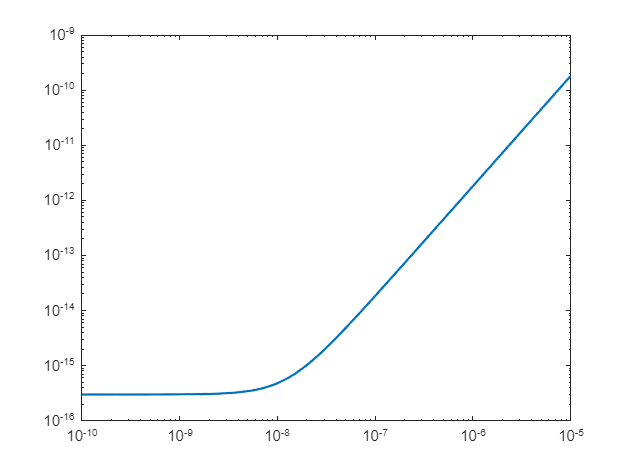


N = -10:0.01:-5;
h = 10.^N;

f_prime = @(x) (cos(x).*exp(cos(x))-(sin(x).^2).*exp(cos(x)));
f_approx = @(x, h) ((f(x+h)-f(x-h))./(2.*h));
error_f = @(h) (abs(f_prime(0) - f_approx(0, h)));

error = error_f(vpa(h));
loglog(h, error_f(vpa(h)), 'LineWidth', 1.5);